# Equlibrium analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

cmap_temp = [[0 0.4470 0.7410];[0.8500 0.3250 0.0980];[0.9290 0.6940 0.1250];[0.4940 0.1840 0.5560]];

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
Prefix = ["2020-11-21-optoknirps_eve4_6_embryo5", "2020-11-22-optoknirps_eve4_6_embryo6","2020-11-24-optoknirps_eve4_6_embryo7","2020-11-27-optoknirps_eve4_6_embryo8"];
numData = length(Prefix);

Initialize some parameters

% eYFP background (estimated from data)
eYFP_background = 2.5E5;

### Create color map

Green color map v1

cmap_green = uint8([[247,252,245];[229,245,224];[199,233,192];[161,217,155];[116,196,118];[65,171,93];[35,139,69];[0,109,44];[0,68,27]]);

old_stepNum = size(cmap_green,1);
new_stepNum = 256;

cmap_green_1 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,1)),linspace(0,1,new_stepNum));
cmap_green_2 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,2)),linspace(0,1,new_stepNum));
cmap_green_3 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,3)),linspace(0,1,new_stepNum));

cmap_green_new = [cmap_green_1' cmap_green_2' cmap_green_3']/256;

Green color map v2

cmap_green_v2 = [[247,252,253];[229,245,249];[204,236,230];[153,216,201];[102,194,164];[65,174,118];[35,139,69];[0,109,44];[0,68,27]];

old_stepNum = size(cmap_green_v2,1);
new_stepNum = 256;

cmap_green_1_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,1)),linspace(0,1,new_stepNum));
cmap_green_2_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,2)),linspace(0,1,new_stepNum));
cmap_green_3_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,3)),linspace(0,1,new_stepNum));

cmap_green_new_v2 = [cmap_green_1_v2' cmap_green_2_v2' cmap_green_3_v2']/256;

Red color map v1

cmap_red = [[255,255,229];[255,247,188];[254,227,145];[254,196,79];[254,153,41];[236,112,20];[204,76,2];[153,52,4];[102,37,6]];

old_stepNum = size(cmap_red,1);
new_stepNum = 256;

cmap_red_1 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,1)),linspace(0,1,new_stepNum));
cmap_red_2 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,2)),linspace(0,1,new_stepNum));
cmap_red_3 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,3)),linspace(0,1,new_stepNum));

cmap_red_new = [cmap_red_1' cmap_red_2' cmap_red_3']/256;

### Color for lines

color_green = [38 143 75]/256;
color_red = [209 82 5]/256;

left_color = color_green;
right_color = color_red;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/combined_data'];

% Make result path
ResultPath = ['./result/combined_data'];

mkdir(FigPath)

mkdir(ResultPath)

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to the analyzed data
LoadDataPath =  "./result/" + Prefix + "/CompiledData.mat"; 

for i = 1:numData
    Data(i) = load(LoadDataPath(i));
end

% load parameters
binNum = Data(1).binNum;
timeFinal = Data(1).timeFinal;
edges = Data(1).edges;

## Part 2: Average data

nuclearFluoAPTemp = zeros(binNum-1,length(timeFinal),numData);
spotFluoAPTemp = zeros(binNum-1,length(timeFinal),numData);

timeOnAPTemp = zeros(binNum-1,numData);
meanRateAPTemp = zeros(binNum-1,numData);

timeOnAllPTemp = zeros(binNum-1,numData);
meanRateAllAPTemp = zeros(binNum-1,numData);

for i = 1:numData
    nuclearFluoAPTemp(:,:,i) = Data(i).nuclearFluoAPFinal';
    spotFluoAPTemp(:,:,i) = Data(i).spotFluoAPFinal';
    timeOnAPTemp(:,i) = Data(i).timeOnAP;
    meanRateAPTemp(:,i) = Data(i).meanRateAP;
    timeOnAllAPTemp(:,i) = Data(i).timeOnAllAP;
    meanRateAllAPTemp(:,i) = Data(i).meanRateAllAP;
end

meanRateAPCombined = mean(meanRateAPTemp,2);
meanRateAPStdCombined = std(meanRateAPTemp,0,2);
meanRateAPErrCombined = meanRateAPStdCombined/sqrt(numData);

timeOnAPCombined = mean(timeOnAPTemp,2);
timeOnAPStdCombined = std(timeOnAPTemp,0,2);
timeOnAPErrCombined = timeOnAPStdCombined/sqrt(numData);

meanRateAllAPCombined = mean(meanRateAllAPTemp,2);
meanRateAllAPStdCombined = std(meanRateAllAPTemp,0,2);
meanRateAllAPErrCombined = meanRateAllAPStdCombined/sqrt(numData);

timeOnAllAPCombined = mean(timeOnAllAPTemp,2);
timeOnAllAPStdCombined = std(timeOnAllAPTemp,0,2);
timeOnAllAPErrCombined = timeOnAllAPStdCombined/sqrt(numData);

nuclearFluoAPCombined = mean(nuclearFluoAPTemp,3)-eYFP_background;
nuclearFluoAPStdCombined = std(nuclearFluoAPTemp,0,3);
nuclearFluoAPErrCombined = nuclearFluoAPStdCombined/sqrt(numData);

spotFluoAPCombined = mean(spotFluoAPTemp,3);
spotFluoAPStdCombined = std(spotFluoAPTemp,0,3);
spotFluoAPErrCombined = spotFluoAPStdCombined/sqrt(numData);

## Part 3: Plot average data

### Plot dynamics

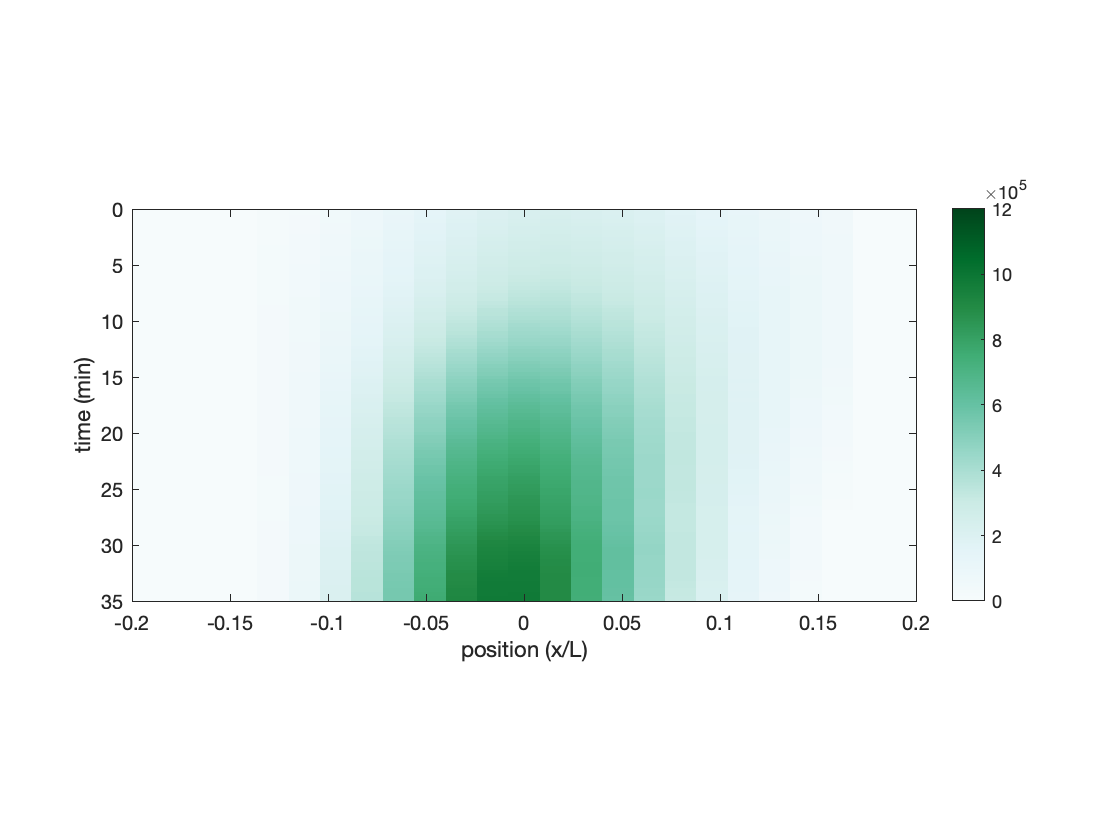

% calculate bin AP position
binAP = (edges(1:end-1)+edges(2:end))/2;

fig = figure;
imagesc(binAP,timeFinal,nuclearFluoAPCombined')
colorbar
colormap(cmap_green_new_v2)
caxis([0 12E5])
pbaspect([2 1 1])
ylim([0 35])
xlabel('position (x/L)')
ylabel('time (min)')

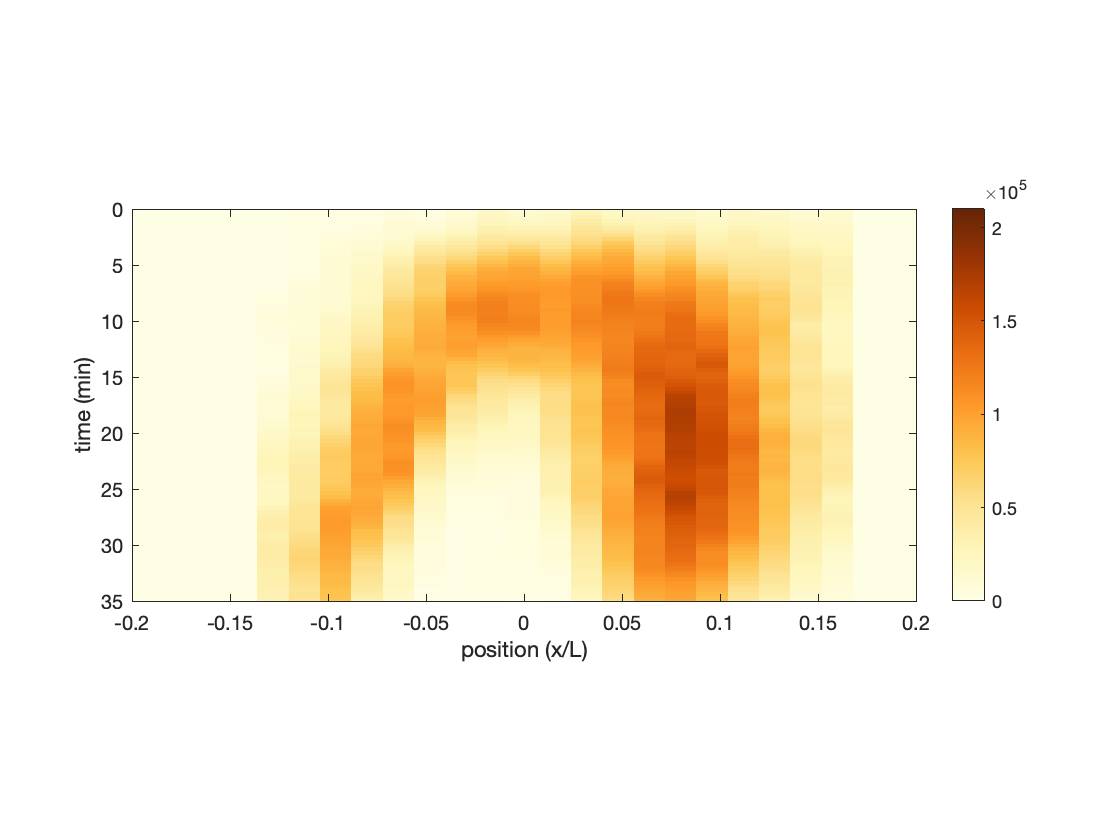

fig1 = figure;
imagesc(binAP,timeFinal,spotFluoAPCombined')
colormap(cmap_red_new)
colorbar
caxis([0 21E4])
pbaspect([2 1 1])
ylim([0 35])
xlabel('position (x/L)')
ylabel('time (min)')

### Plot temporal dynamics for each bin

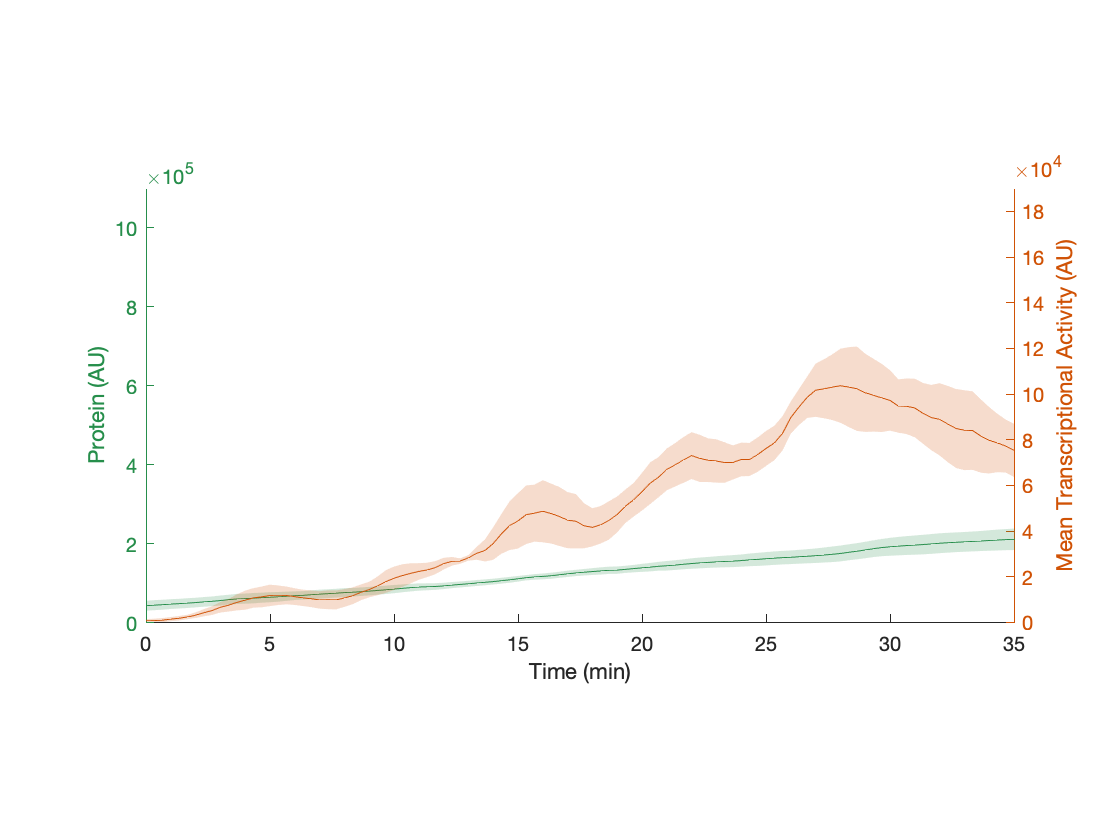

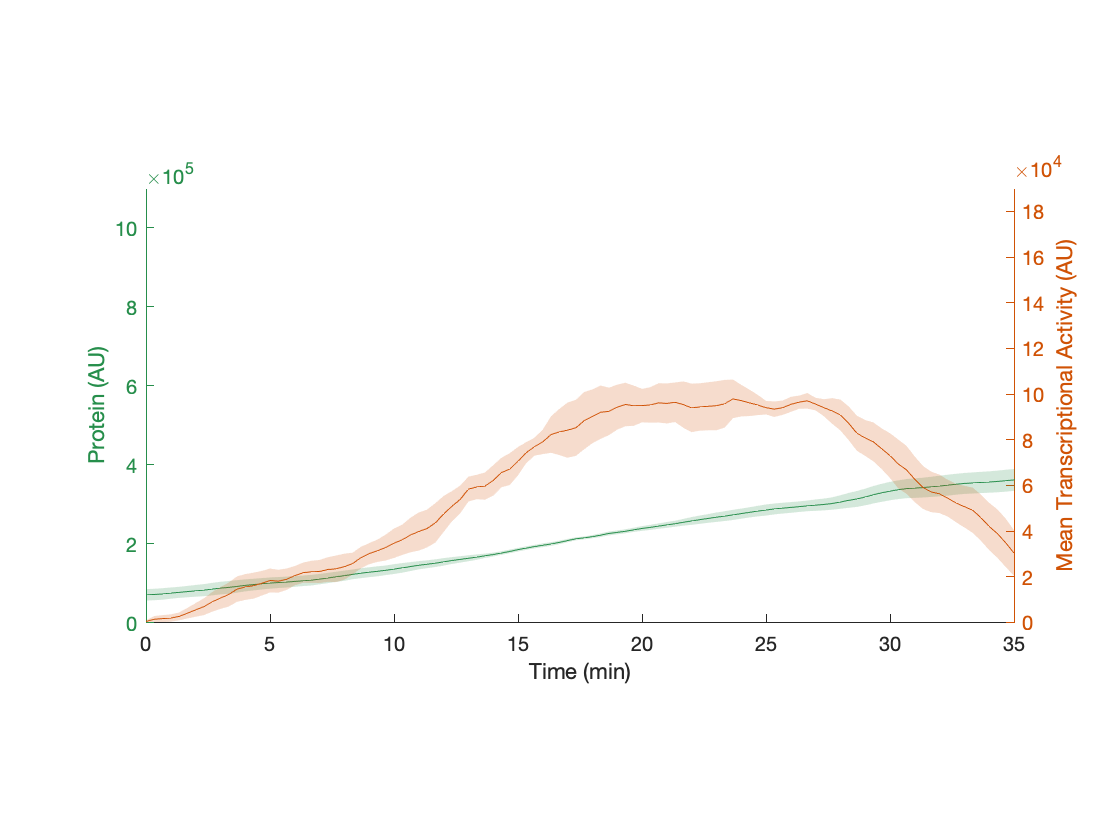

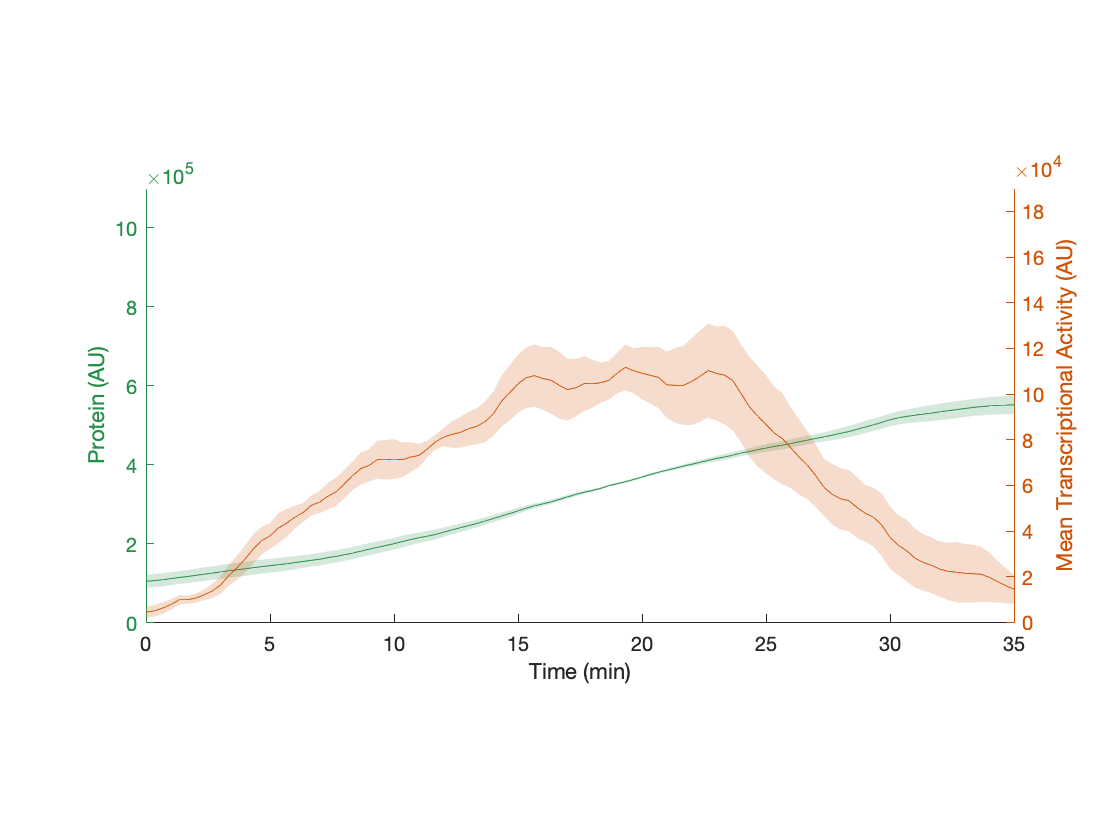

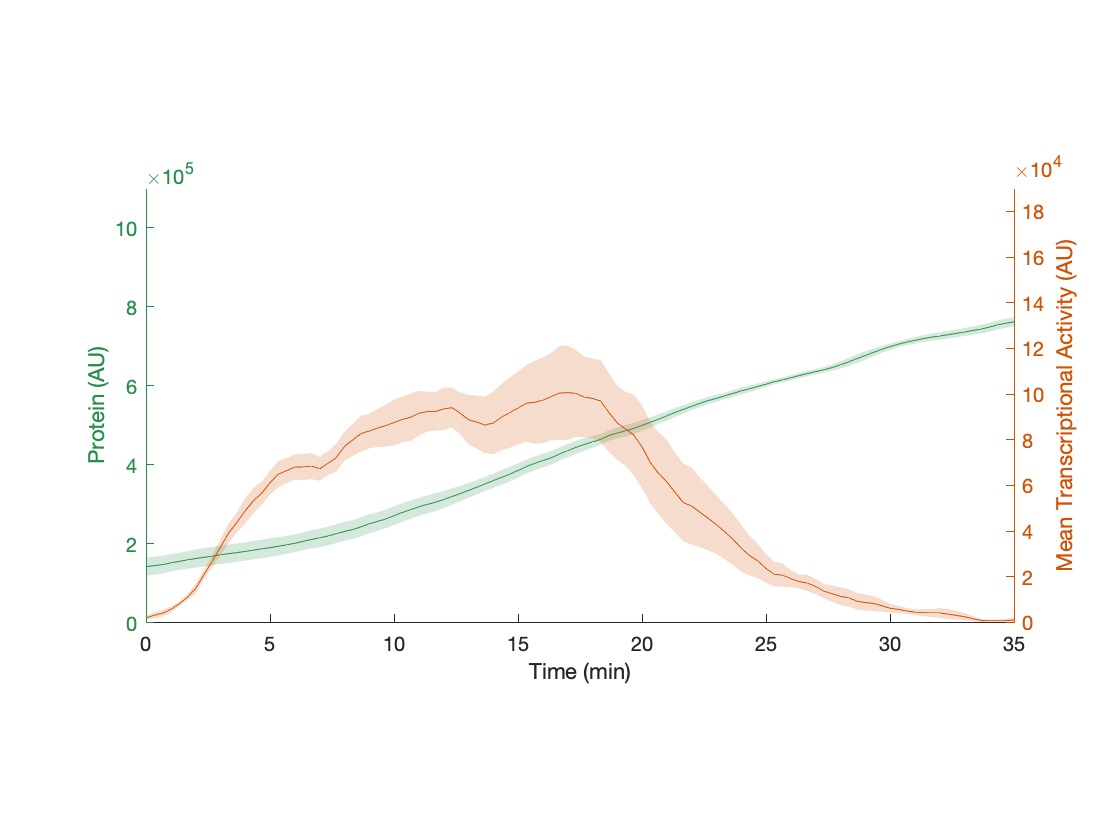

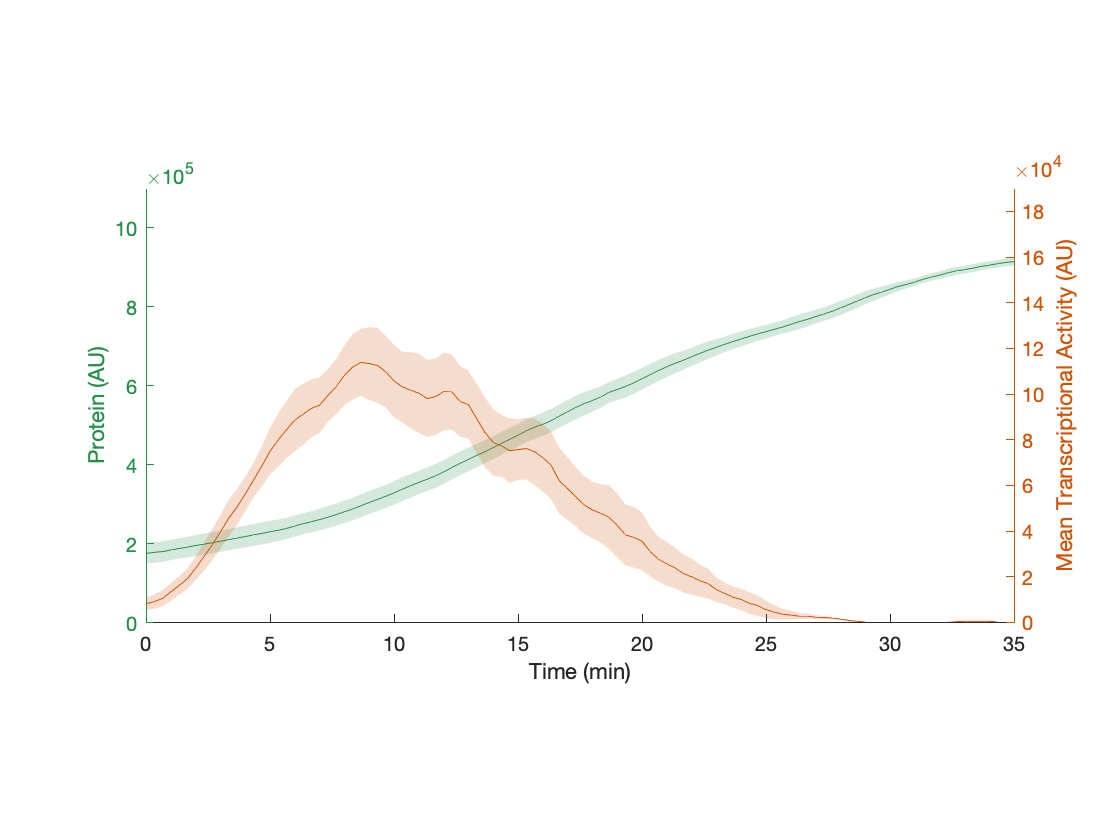

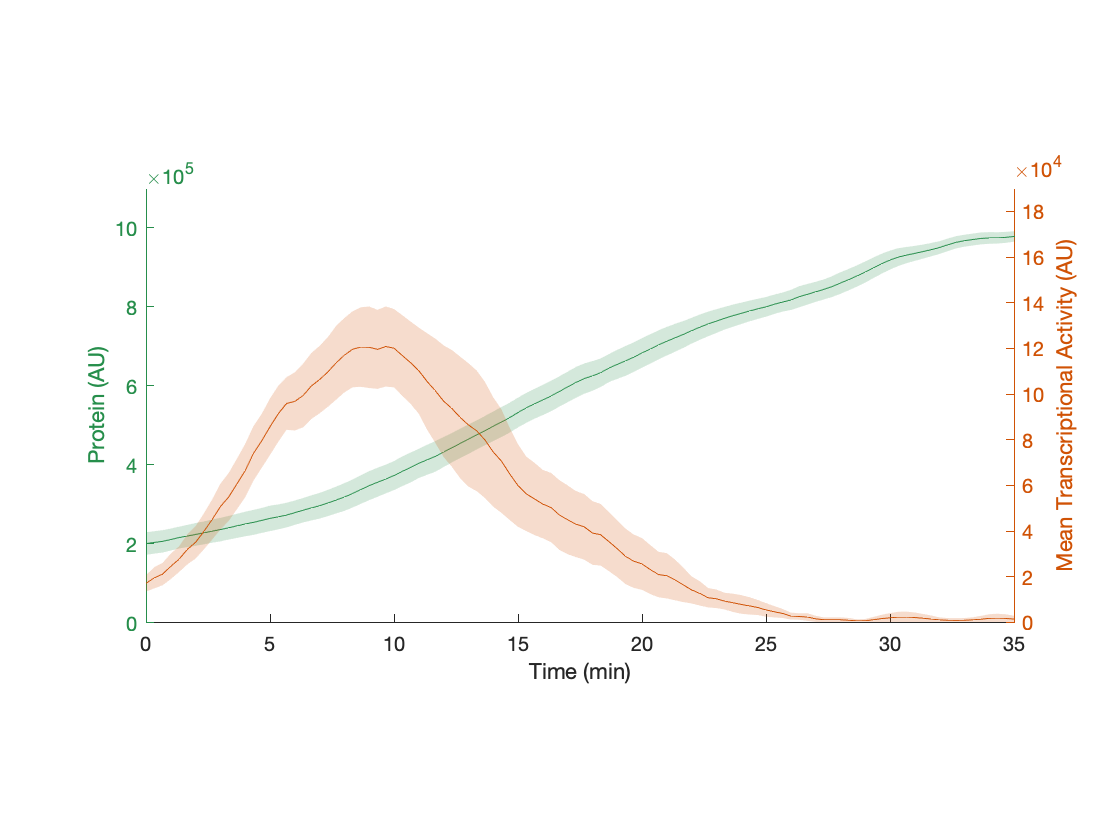

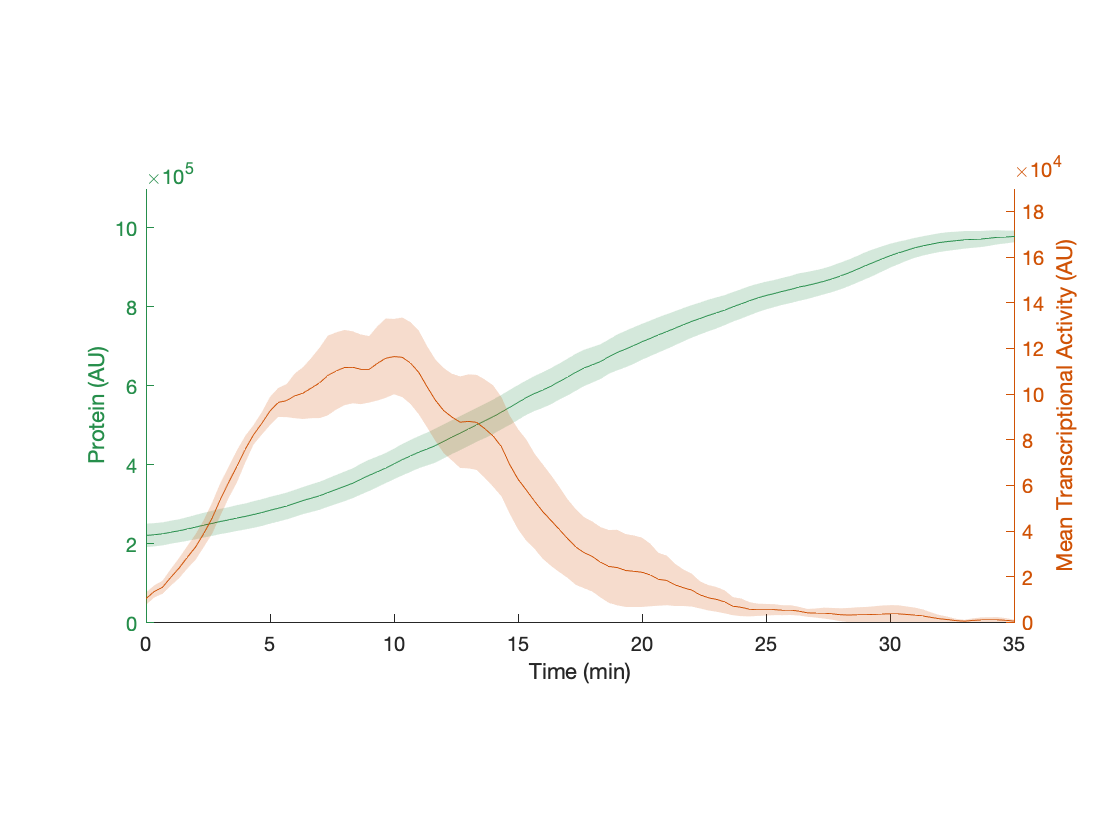

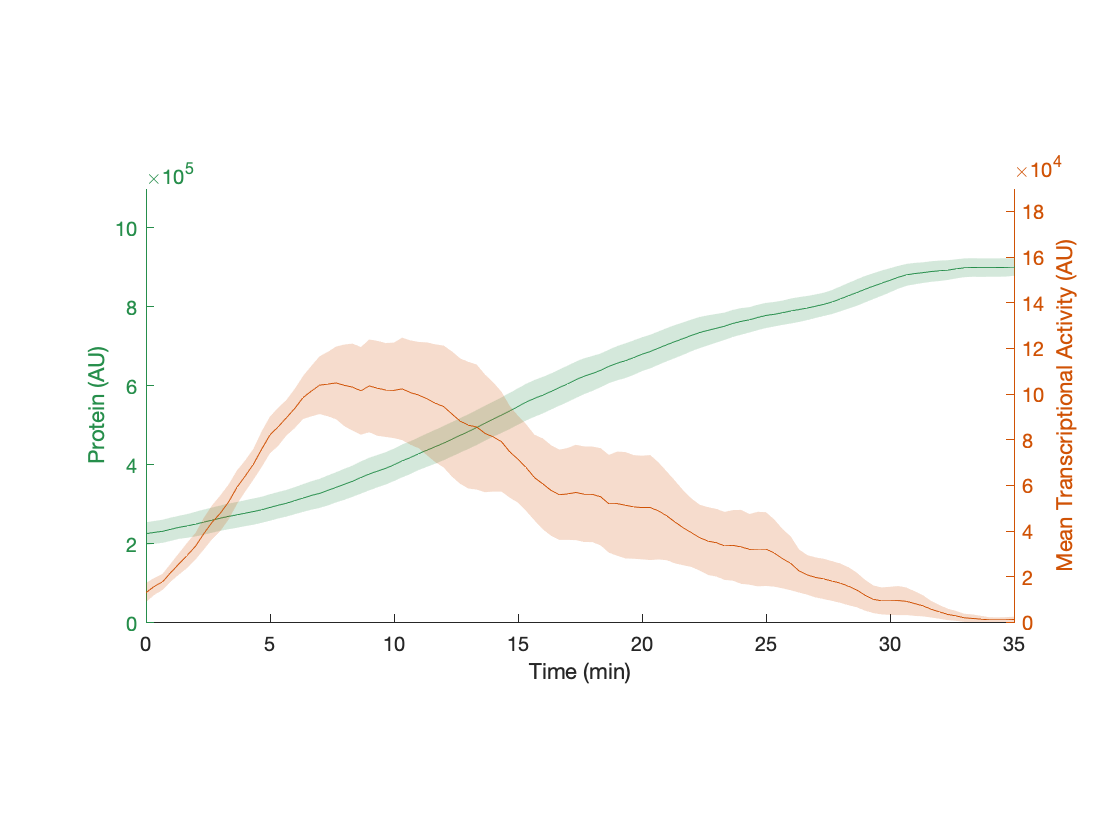

binRange = 7:19;

for i = 1:length(binRange)
    
    bin_plot = binRange(i);
    
    AvrBinProteinFig = figure;  
    %protein_err_plot = [protein_err(bin_plot,:) ]
    set(AvrBinProteinFig,'defaultAxesColorOrder',[left_color; right_color]);
    
    yyaxis left
    boundedline(timeFinal, nuclearFluoAPCombined(bin_plot,:),nuclearFluoAPErrCombined(bin_plot,:), '-','nan', 'gap','alpha','cmap', left_color);
    ylabel('Protein (AU)')
    %ylim([1E5 7.5E5])
    ylim([0 11E5])
    
    yyaxis right
    boundedline(timeFinal, spotFluoAPCombined(bin_plot,:),spotFluoAPErrCombined(bin_plot,:), '-','nan', 'gap','alpha','cmap', right_color);
    ylim([0 1.9E5])
    ylabel('Mean Transcriptional Activity (AU)')
    xlim([0 35])
    
    pbaspect([2 1 1])
    xlabel('Time (min)')
end

### Plot for specific timepoints

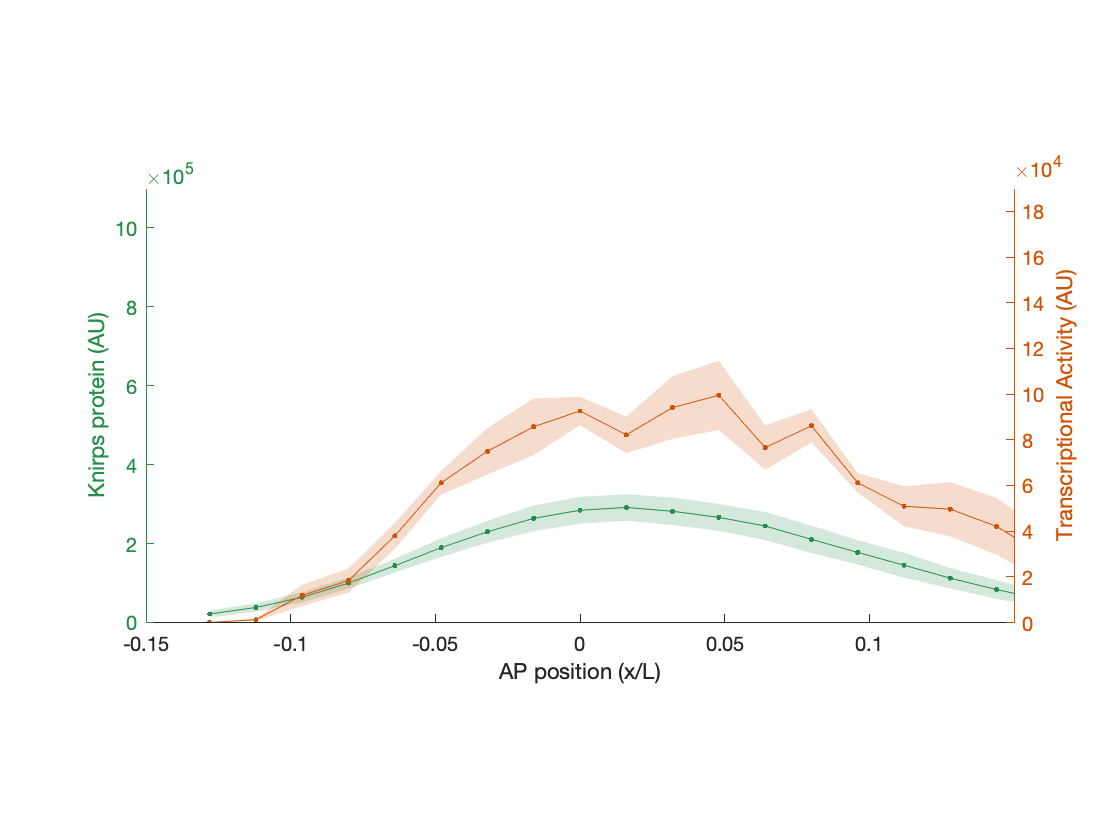

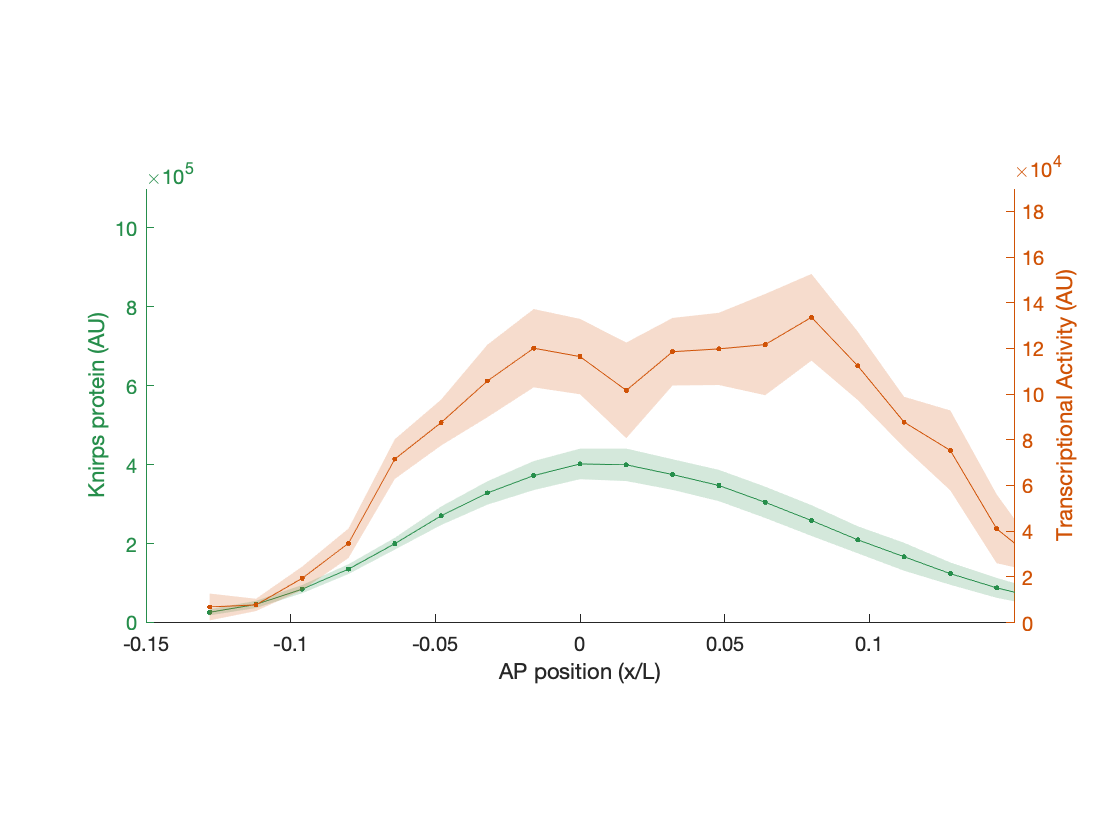

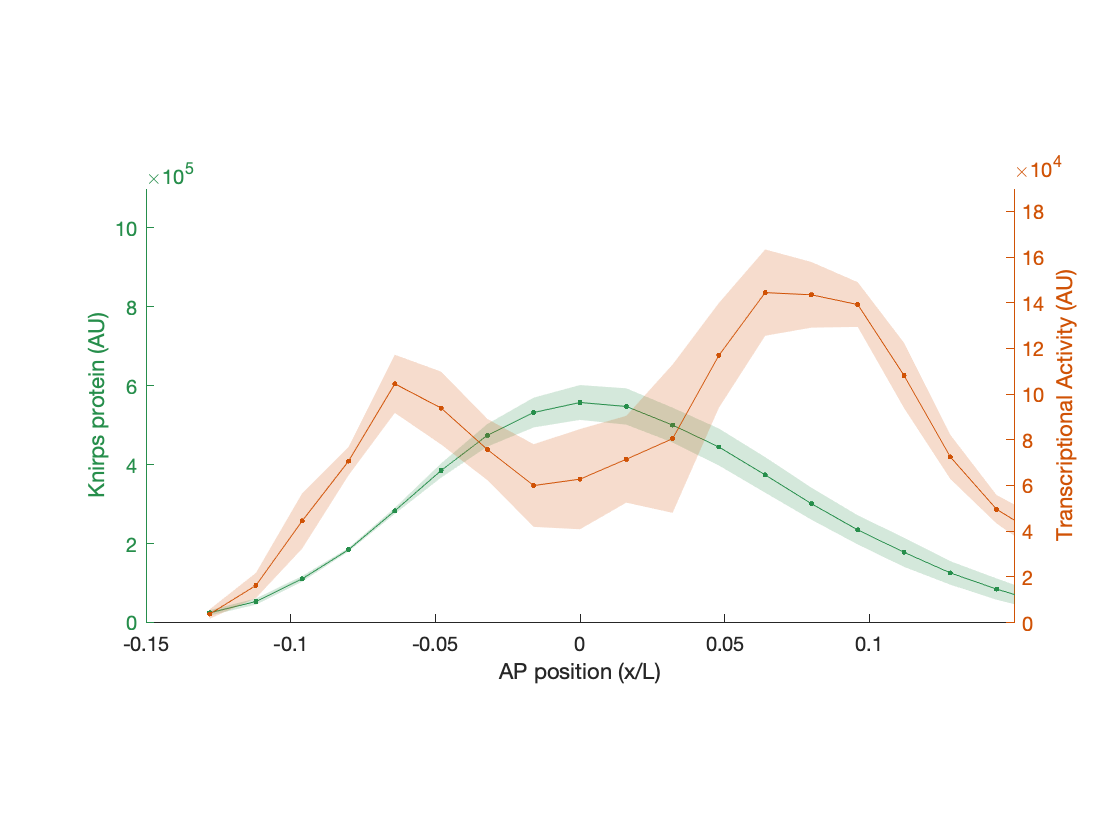

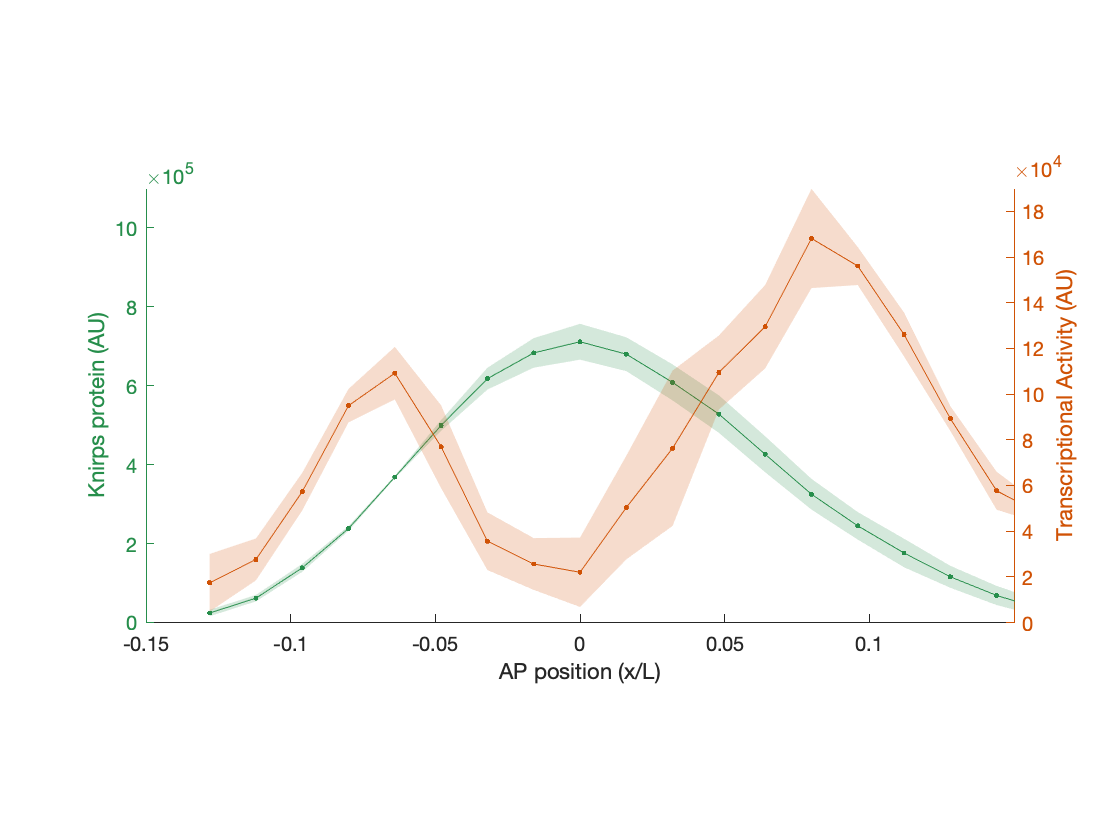

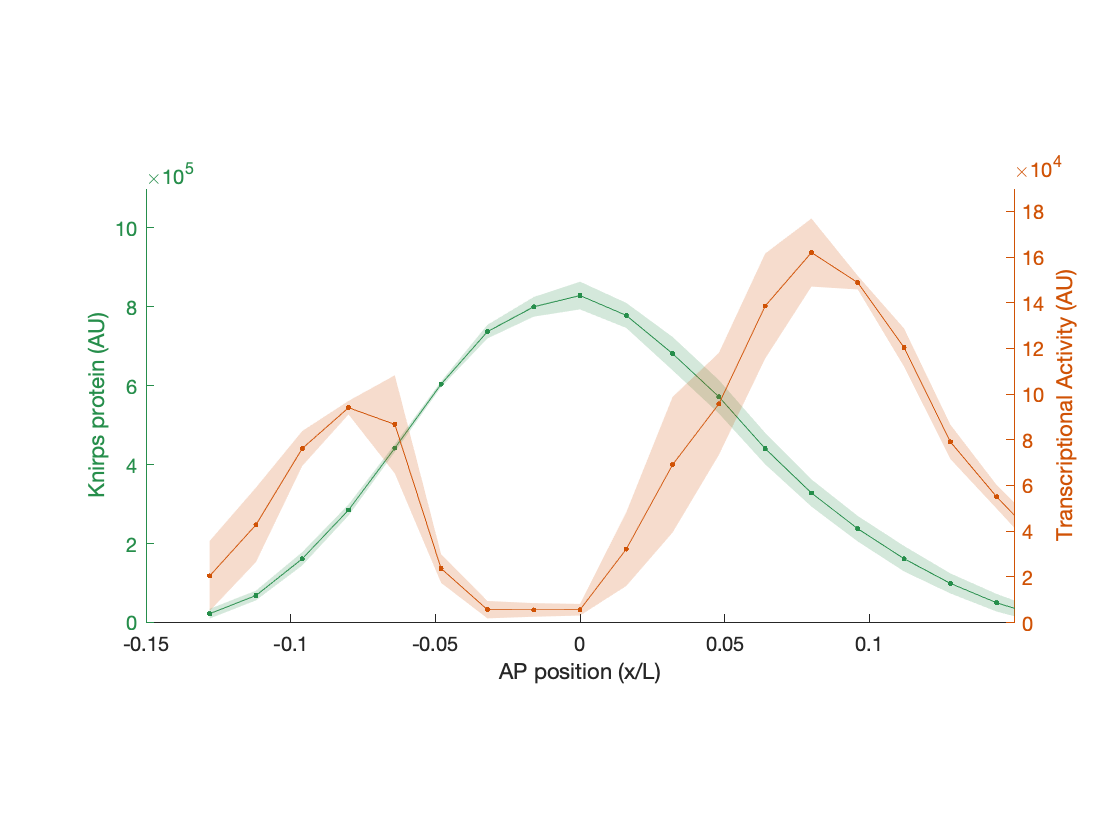

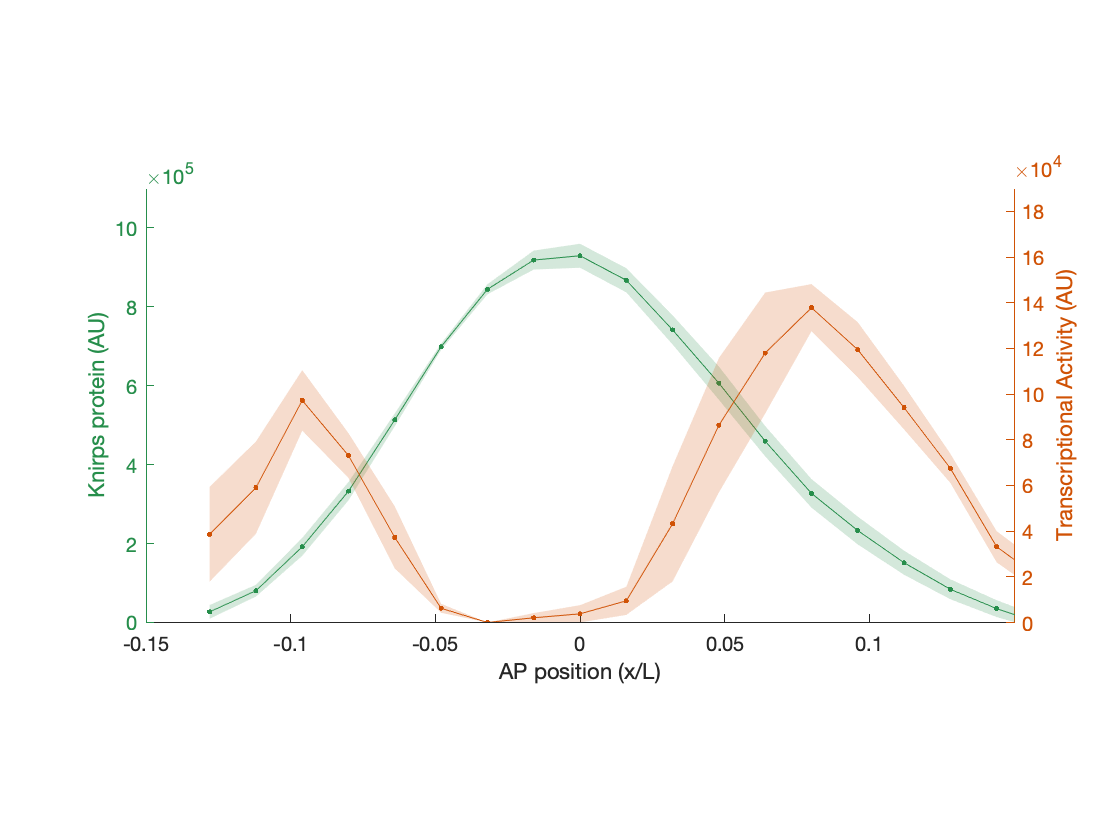

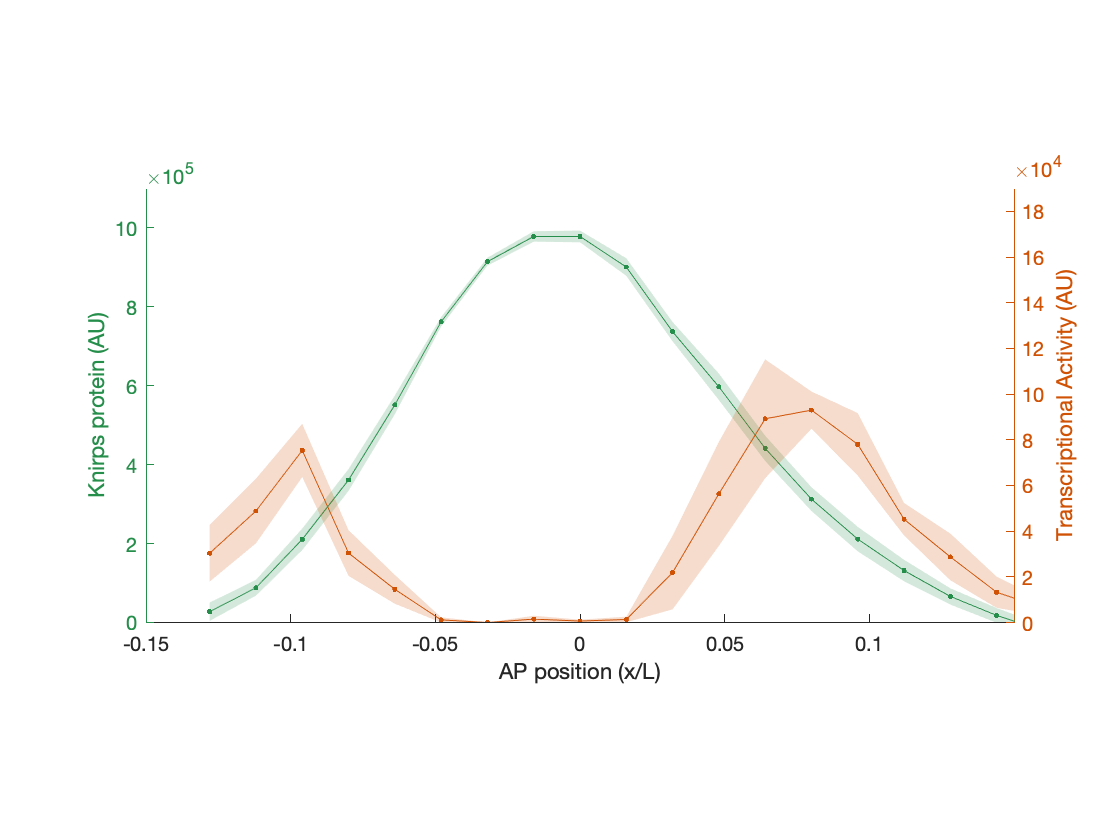

timeRange = [16 31 46 61 76, 91, 106];

for i = 1:length(timeRange)
    
    time_plot = timeRange(i);
    
    TimePlotFig = figure;  
    %protein_err_plot = [protein_err(bin_plot,:) ]
    set(TimePlotFig,'defaultAxesColorOrder',[left_color; right_color]);
    
    yyaxis left
    boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
    ylabel('Knirps protein (AU)')
    ylim([0 11E5])
    
    yyaxis right
    boundedline(binAP, spotFluoAPCombined(:,time_plot),spotFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', right_color);
    ylabel('Transcriptional Activity (AU)')
    ylim([0 1.9E5])
    
    pbaspect([2 1 1])
    xlabel('AP position (x/L)')
    xlim([-0.15 0.15])
end

### Plot time on and mean rate

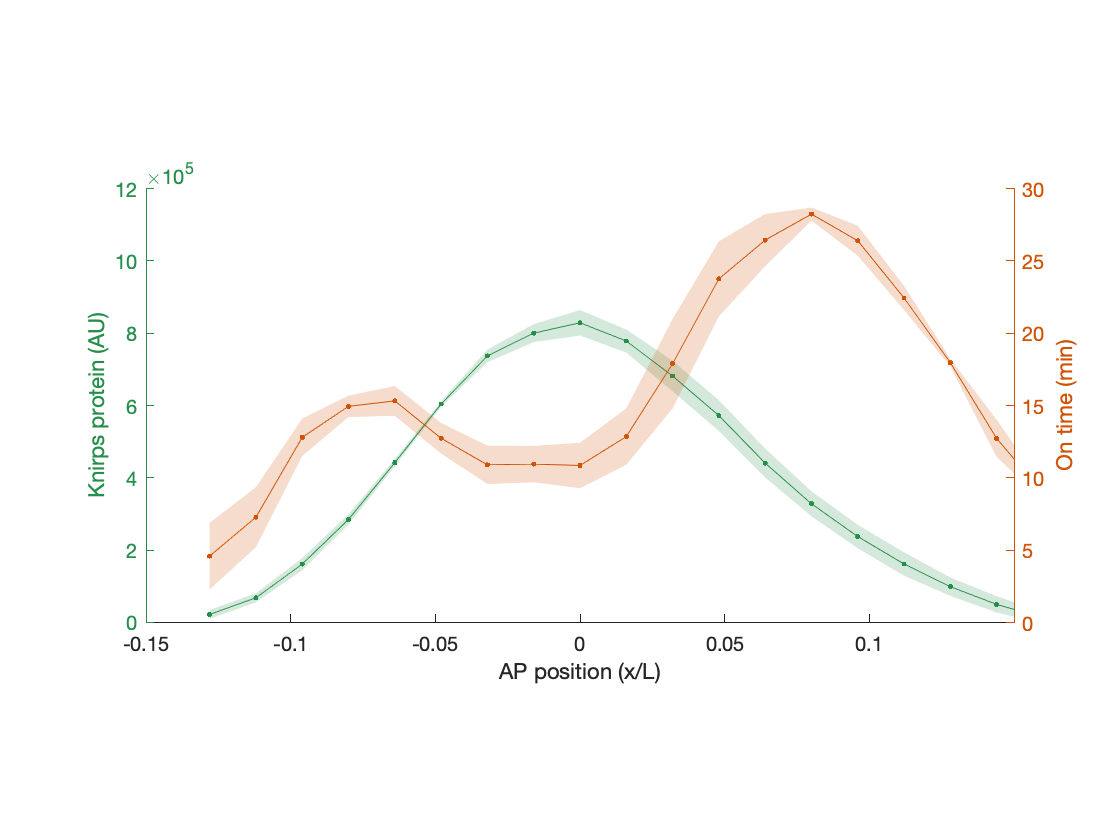

time_plot = 76;

MeanRateFig = figure;

set(MeanRateFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, timeOnAPCombined,timeOnAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 30])
ylabel('On time (min)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.15 0.15])

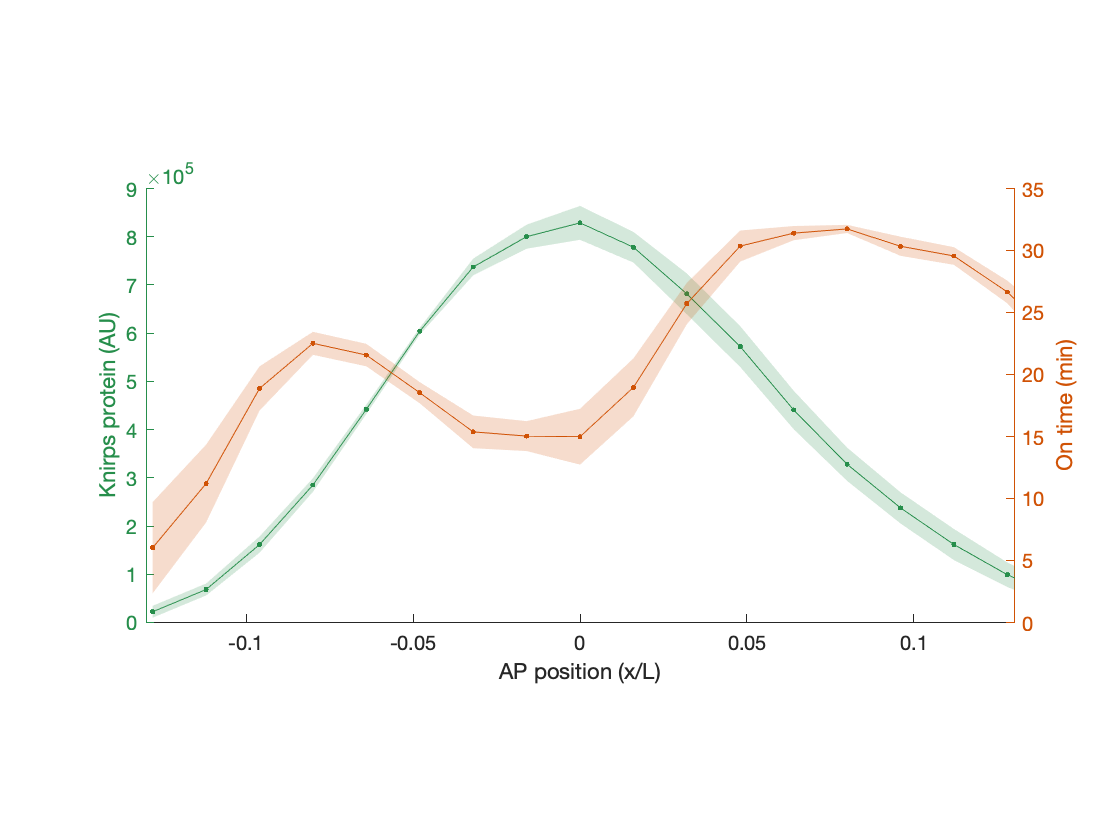

MeanRateAllFig = figure;

set(MeanRateAllFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 9E5])

yyaxis right
boundedline(binAP, timeOnAllAPCombined,timeOnAllAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 35])
ylabel('On time (min)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])

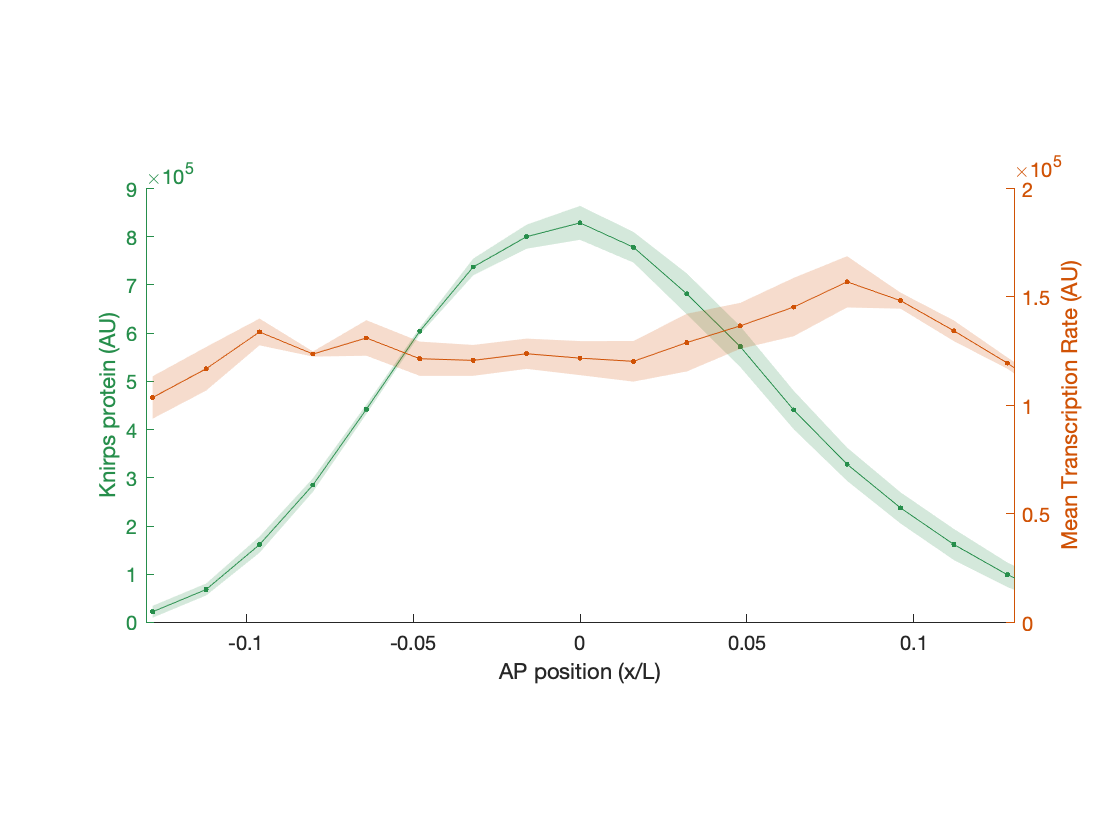


TimeOnFig = figure;
set(TimeOnFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 9E5])

yyaxis right
boundedline(binAP, meanRateAPCombined,meanRateAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 2E5])
ylabel('Mean Transcription Rate (AU)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])

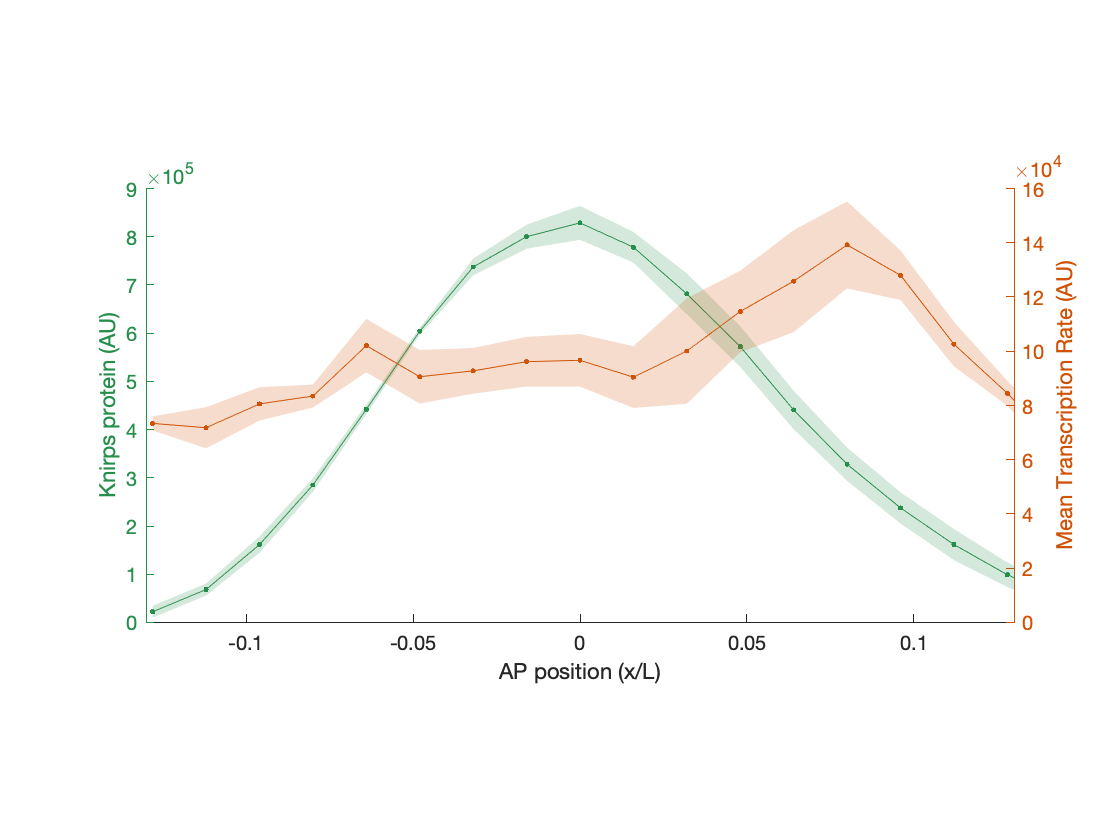

TimeOnAllFig = figure;
set(TimeOnAllFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 9E5])

yyaxis right
boundedline(binAP, meanRateAllAPCombined,meanRateAllAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 1.6E5])
ylabel('Mean Transcription Rate (AU)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])

### Plot input-output functions

% MeanRateIOFig = figure;
% 
% plot(nuclearFluoAPCombined(:,time_plot),meanRateAPCombined,'o');
% xlim([5E5 8.5E5])
% ylim([0 2E5])
% xlabel('Knirps protein (AU)')
% ylabel('Mean Transcription Rate (AU)')
% pbaspect([2 3 1])
% TimeOnIOFig = figure;
% 
% plot(nuclearFluoAPCombined(:,time_plot),timeOnAPCombined,'o');
% xlim([5E5 8.5E5])
% ylim([0 30])
% xlabel('Knirps protein (AU)')
% ylabel('ON Time (min)')
% pbaspect([2 3 1])